% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

% ********** 1) Baseline Models **********

% 1a) Baseline Decision Tree
disp('Baseline Decision Tree')

Baseline Decision Tree


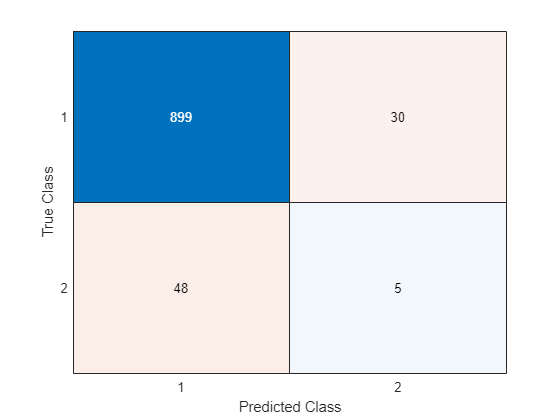

accuracy = 0.9206

precision = 0.1429

recall = 0.0943

specificity = 0.9677

f05 = 0.1136

% Train
dt_base = fitctree(X_train, y_train);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

% 1b) Baseline Random Forest
disp('Baseline Random Forest')

Baseline Random Forest


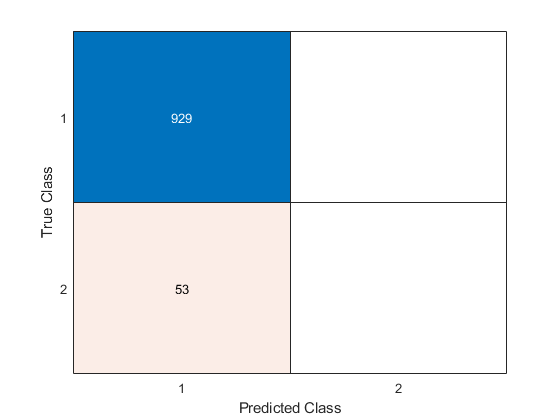

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

f05 = 0

% Train
rf_base = fitcensemble(X_train, y_train, 'Method', 'Bag');
% Evaluate
test_model(rf_base, X_test, y_test)

% 1c) Baseline KNN
disp('Baseline KNN')

Baseline KNN


accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

f05 = 0

% Train
knn_base = fitcknn(X_train, y_train, 'NumNeighbors', 2 ,'Standardize',1);
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

% ********** 2) Tuned Models **********

% 2a) Optimized Tree with CV
% Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train)

nrow = 3926

ncol = 17

c= cvpartition(nrow,'KFold', 10)

c = K-fold cross validation partition
   NumObservations: 3926
       NumTestSets: 10
         TrainSize: 3534  3533  3533  3533  3533  3533  3533  3534  3534  3534
          TestSize: 392  393  393  393  393  393  393  392  392  392

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |      MinLeaf |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.83588 |    0.071478 |     0.83588 |     0.83588 |            7 |            7 |
|    2 | Accept |     0.85157 |    0.081655 |     0.83588 |     0.83698 |           30 |           33 |
|    3 | Accept |     0.84557 |    0.078798 |     0.83588 |     0.83588 |           38 |           16 |
|    4 | Accept |     0.84284 |    0.070677 |     0.83588 |     0.84024 |           23 |           42 |
|    5 | Accept |     0.84086 |    0.090239 |     0.83588 |     0.83588 |           11 |           45 |
|    6 | Best   |     0.82872 |    0.080641 |     0.82872 |     

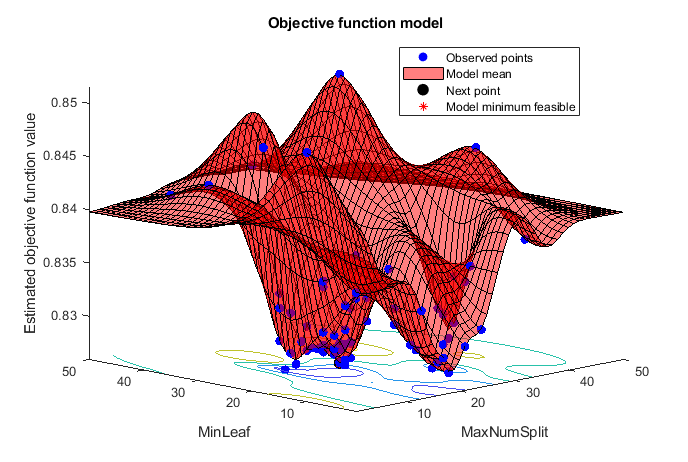

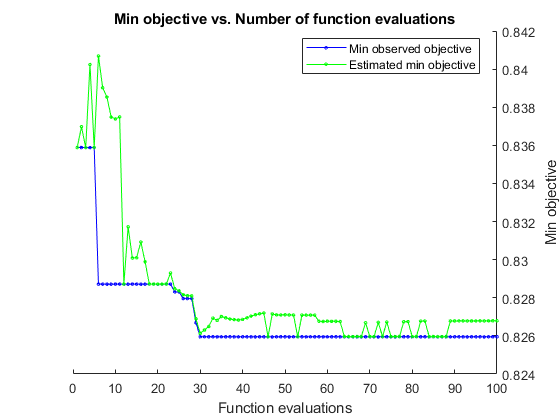


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 40.1673 seconds
Total objective function evaluation time: 7.6553

Best observed feasible point:
    MaxNumSplit    MinLeaf
    ___________    _______

        14           27   

Observed objective function value = 0.82595
Estimated objective function value = 0.82767
Function evaluation time = 0.073466

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeaf
    ___________    _______

        18           21   

Estimated objective function value = 0.82679
Estimated function evaluation time = 0.075993




% Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1,50],'Type','integer');
MinLeaf = optimizableVariable('MinLeaf',[1, 50],'Type','integer');
ParamsDT= [MaxNumSplit; MinLeaf];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_dt_cv(params,X_train,y_train, c), ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

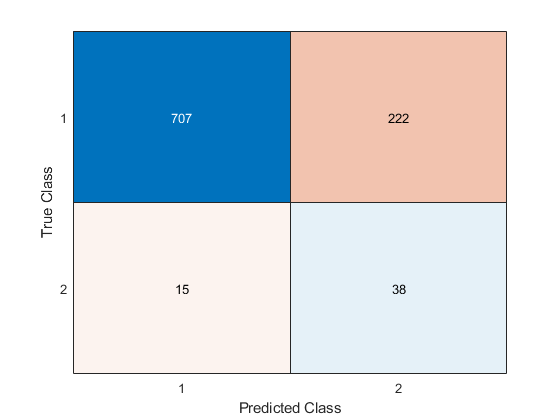

accuracy = 0.7587

precision = 0.1462

recall = 0.7170

specificity = 0.7610

f05 = 0.2428


% Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'prior', 'uniform', 'MaxNumSplits', z.MaxNumSplit, 'MinLeafSize', z.MinLeaf);

% Evaluate
test_model(dt_best, X_test, y_test)

% 2b) Optimized Random Forest with CV - TOOD: Implement!
% Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train)
c= cvpartition(nrow,'KFold', 10)

% Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1,50],'Type','integer');
MinLeaf = optimizableVariable('MinLeaf',[1, 50],'Type','integer');
ParamsRF= [MaxNumSplit; MinLeaf];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_rf_cv(params,X_train,y_train, c), ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitcensemble(X_train, y_train, 'prior', 'uniform', 'MaxNumSplits', z.MaxNumSplit, 'MinLeafSize', z.MinLeaf);

% Evaluate
test_model(dt_best, X_test, y_test)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.82005 |     0.10715 |     0.82005 |     0.82005 |            6 |    euclidean |
|    2 | Best   |     0.80717 |     0.12388 |     0.80717 |     0.81361 |            6 |    chebychev |
|    3 | Accept |     0.81586 |     0.10578 |     0.80717 |     0.80882 |            5 |    euclidean |
|    4 | Accept |     0.84663 |     0.10753 |     0.80717 |     0.80724 |           19 |    euclidean |
|    5 | Accept |     0.83558 |    0.095622 |     0.80717 |     0.80718 |           13 |    chebychev |
|    6 | Accept |     0.81278 |     0.09496 |     0.80717 |     

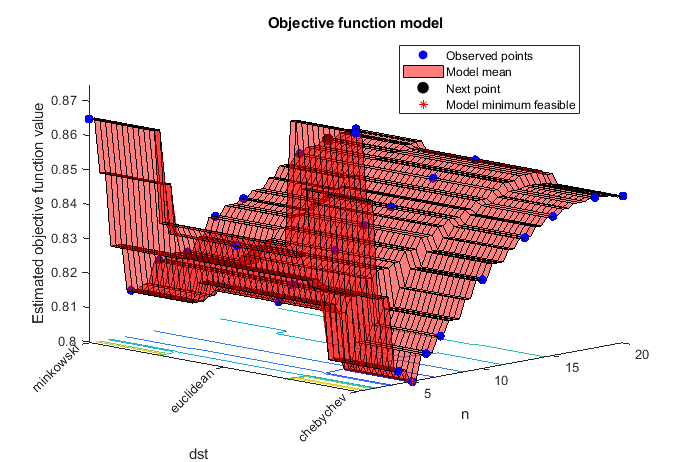

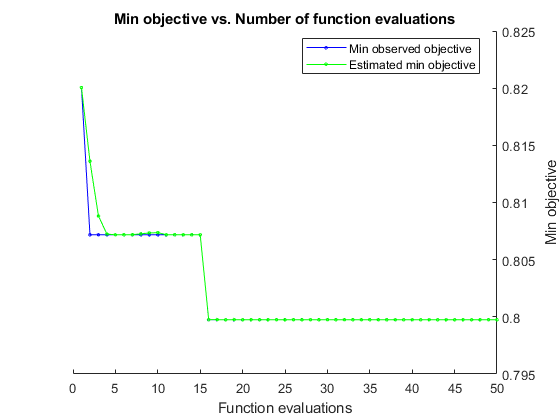


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 21.3994 seconds
Total objective function evaluation time: 4.6575

Best observed feasible point:
    n       dst   
    _    _________

    5    chebychev

Observed objective function value = 0.79975
Estimated objective function value = 0.79975
Function evaluation time = 0.080354

Best estimated feasible point (according to models):
    n       dst   
    _    _________

    5    chebychev

Estimated objective function value = 0.79975
Estimated function evaluation time = 0.091871



% 2c) Optimized KNN with CV
% Define vars and range
n = optimizableVariable('n',[1,20],'Type','integer');
dst = optimizableVariable('dst', {'chebychev','euclidean','minkowski'},'Type','categorical');
ParamsKNN= [n; dst];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_knn_cv(params,X_train,y_train, c), ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

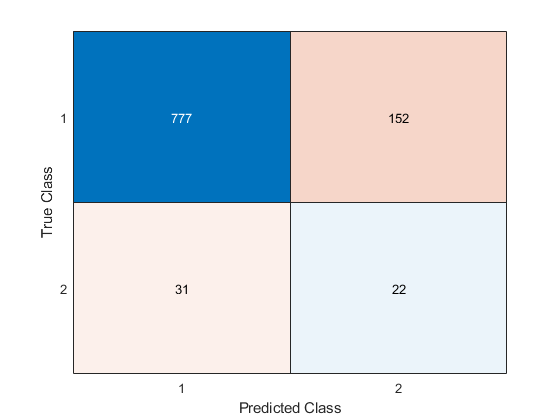

accuracy = 0.8136

precision = 0.1264

recall = 0.4151

specificity = 0.8364

f05 = 0.1938


% Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train,'NSMethod','exhaustive', 'Prior', 'uniform',...
            'NumNeighbors', z.n, 'Distance', char(z.dst));

% Evaluate
test_model(knn_best, X_test, y_test)

function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    % Evaluation metrics for binary classification
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end

% Test model without CV folds
function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    confusionchart(cmat);
    [accuracy, precision, recall, specificity, f05] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        model = fitctree(X_train, y_train, 'prior', 'uniform', 'CVPartition', cv_part, ...
            'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeaf);
        
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'CVPartition', cv_part, 'Method', 'Bag', 'exhaustive', 'prior', 'uniform',...
            'NumNeighbors', params.n, 'Distance', char(params.dst));
        
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end
% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'CVPartition', cv_part, 'NSMethod', 'exhaustive', 'prior', 'uniform',...
            'NumNeighbors', params.n, 'Distance', char(params.dst));
        
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end



%#ok<*ASGLU,*NOPRT> 